clc,clear,close all

# Constants

g=9.81; %m/s^2
k1=1.6e-3;
k2=3.62e-3;
Ix=5.8e-5

Ix = 5.8000e-05

Iy=7.2e-5

Iy = 7.2000e-05

## Eigenvalues at Varying k3 Gains

k3=linspace(1e-3,1e-4,50);
e=zeros(3,length(k3))

e =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


gcf

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


hold on

for i=1:length(k3)

A=[-k1/Ix,-k2/Ix,-k3(i)/Ix;...]
      1,0,0;...
      0,g,0];
  
      e(:,i)=eig(A);
      
end
hold off
realEigs = real(e)

realEigs =   -25.3904  -25.3852  -25.3800  -25.3747  -25.3695  -25.3643  -25.3590  -25.3538  -25.3485  -25.3433  -25.3380  -25.3328  -25.3275  -25.3222  -25.3169  -25.3117  -25.3064  -25.3011  -25.2958  -25.2905  -25.2852  -25.2799  -25.2746  -25.2692  -25.2639  -25.2586  -25.2533  -25.2479  -25.2426  -25.2372  -25.2319  -25.2265  -25.2212  -25.2158  -25.2104  -25.2050  -25.1997  -25.1943  -25.1889  -25.1835  -25.1781  -25.1727  -25.1673  -25.1619  -25.1565  -25.1510  -25.1456  -25.1402  -25.1347  -25.1293
   -1.0979   -1.1005   -1.1031   -1.1057   -1.1084   -1.1110   -1.1136   -1.1162   -1.1188   -1.1215   -1.1241   -1.1267   -1.1294   -1.1320   -1.1346   -1.1373   -1.1399   -1.1426   -1.1452   -1.1479   -1.1505   -1.1532   -1.1558   -1.1585   -1.1611   -1.1638   -1.1665   -1.1691   -1.1718   -1.1745   -1.1772   -1.1798   -1.1825   -1.1852   -1.1879   -1.1906   -1.1933   -1.1960   -1.1987   -1.2014   -1.2041   -1.2068   -1.2095   -1.4496   -1.6463   -1.7797   -1.8880   -1.9819   -2.06

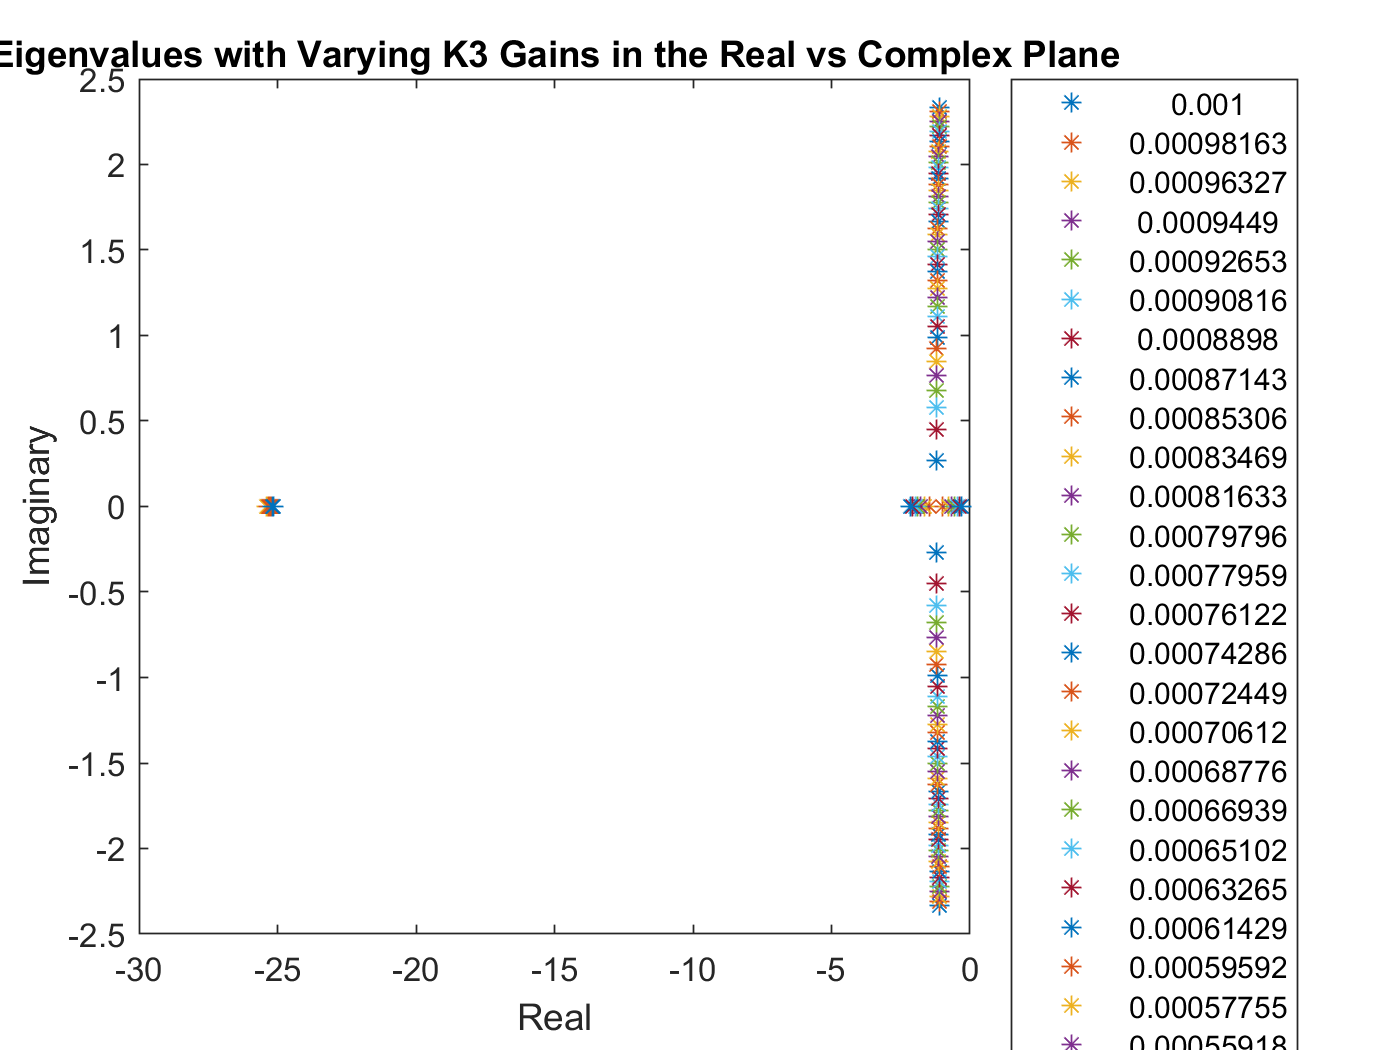


plot(real(e),imag(e),'*')
title('Eigenvalues with Varying K3 Gains in the Real vs Complex Plane')
xlabel('Real')
ylabel('Imaginary')
legend(num2str(k3.'),'Location','bestOutside' )

## Settling Time for Selected gains

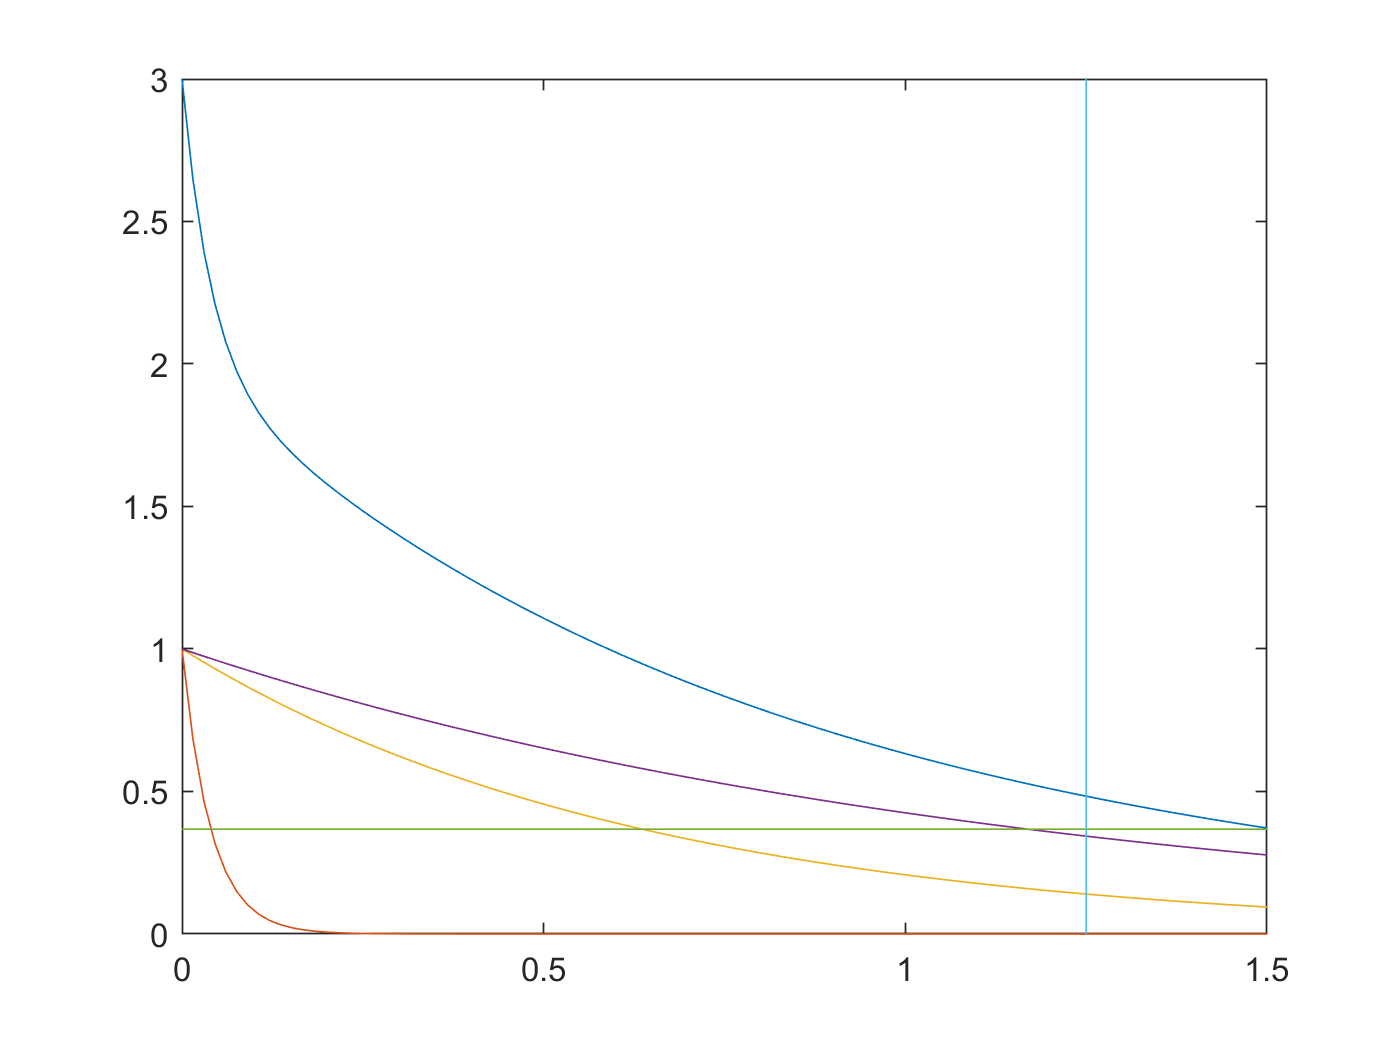




k3=2e-4;

A=[-k1/Ix,-k2/Ix,-k3/Ix;...]
      1,0,0;...
      0,g,0];
  
      e_fin=eig(A);

tau=-1./(e_fin);

t=linspace(0,1.5,100);

y1=exp(e_fin(1)*t);
y2=exp(e_fin(2)*t);
y3=exp(e_fin(3)*t);

y=y1+y2+y3;

plot(t,y)
hold on
plot(t,y1)
plot(t,y2)
plot(t,y3)
plot([0,1.5],[exp(-1),exp(-1)])
plot([1.25,1.25],[0,3])


k4=k1*Iy/Ix;
k5=k2*Iy/Ix;
k6=k3*Iy/Ix;
